# Analyse de l'Information - TP1

17/10/22

Déric Augusto FRANÇA DE SALES

close all; clc; clear all; 

## Création des signaux de transmission d'informations

Testant different tips de codages

### Creation des Signaux

#### Création d'un vecteur de lettres en binaire

s = 'abracaraba';

% create a vector of ASCII caracters from each letter of the string
snum = int8(s);  
% convert to binary in string form
snum = dec2bin(snum)';
% transform the vertical vector in real binary values
sbin = str2num(snum(:));

#### Paramètres de reglage 

spb = 10;         % sample per bit
Tm = 10^-3;       % periode des moments (d'horloge, clock)
Ts = Tm/spb;      % periode d'échantillonnage

N = length(sbin);                  % nombre de caracteres
Fe = 1/Ts;                         % frequence d'échantillonnage
baset = 0 : Ts : (N*Tm - Ts);       % base de temps

Rf = Fe/length(baset);                % resolution fréquentielle
basef = (- Fe/2) : Rf : (Fe/2 - Rf);  % base fréquentielle
v0 = 5;                               % 5 V (valeur maximale du signal)

#### Définition du signal unipolaire

signal = repmat(sbin,1,spb)';
sUnipolaire = signal(:)*v0;

figure; subplot(4,1,1); plot(baset, sUnipolaire); title('signal unipolaire'); 

#### Définition du signal de codage Polaire

sPolaire = 2*(sUnipolaire  - 2.5);

subplot(4,1,2); plot(baset,sPolaire); title('signal polaire'); 

#### Définition du signal clock

% f = 1/Tm
temps = 2*pi*baset/Tm;
clk = 0.5*square(temps) + 0.5;

subplot(4,1,3); plot(baset,clk); title('clock'); 

#### Définition du signal de codage Mancherster

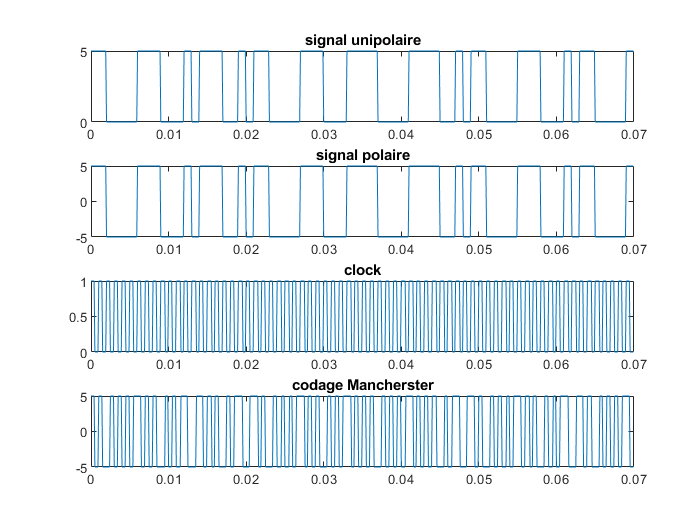

mancherster = xor(sUnipolaire,clk');
sMancherster = -2*v0*(mancherster - 0.5);

subplot(4,1,4); plot(baset,sMancherster); title('codage Mancherster'); 

### Analyse en Fréquence

Aplicant le Fast Fourier Transform dans les signaux:

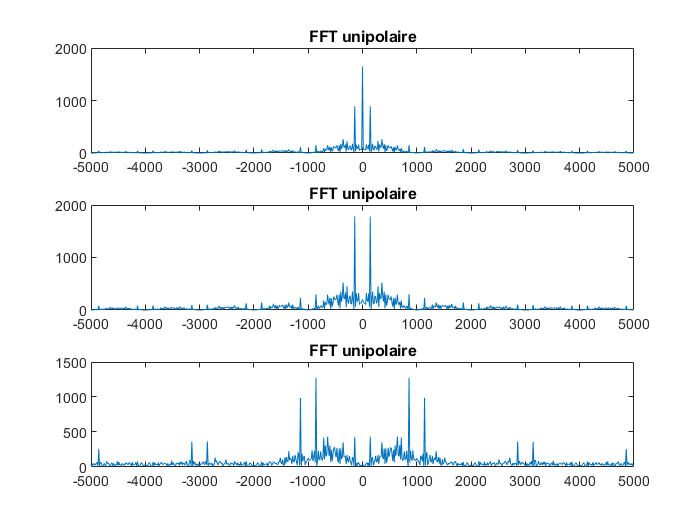

% unipolaire
fft_un = abs(fftshift(fft(sUnipolaire)));
figure; subplot(3,1,1); plot(basef,fft_un); title("FFT unipolaire");
% polaire
fft_pol = abs(fftshift(fft(sPolaire)));
subplot(3,1,2); plot(basef,fft_pol); title("FFT unipolaire");
% Mancherster
fft_man = abs(fftshift(fft(sMancherster)));
subplot(3,1,3); plot(basef,fft_man); title("FFT unipolaire");

O sinal unipolar apresenta uma componente CC, representada em freqência com um sinal de frequência 0. Isso se deve ao fato de a média do sinal não ser 0, então, é como se sua média fosse acrescida a ele, e isso consome energia, para gerar esse sinal mais alto e pode ainda gerar um maior efeito joule no fio. 

O sinal Polar, por sua vez, não apresenta essa componente CC. Ambos os sinais unipolar e polar, precisam serem acompanhados do fio com o clock, para que a informação possa ser extraída dos sinais, através da comparação com o clock. O sinal Mancherster, por sua, vez, não necessita do fio clock. Pela forma que é codificdo já é possível obter o clock do sinal e extraír sua infrormação. Isso, no entanto, tem um custo. Para ser codificado desta forma esse sinal utiliza uma banda de frequência maior para a trasnmissão da informação. Enquanto os sinais polar e unipolar utilizam uma banda de frequência contida entre 0 e a frequência de transmissão de informações (a frequência de clock), o sinal Mancherster utilizará uma banda de frequência duas vezes maior. Isso é um problema já que conterá componentes de frequência duas vezes maiores, e quanto maior a frequência, maior será a perda no fio. Um cabo qualquer funcionará fisicamente como um filtro passa baixa, já que as frequências mais altas sofrem mais perdas no material que as baixas frequências.

### Aujoutant un filtre aux signaux

Ajoutant le filtre Butterworth

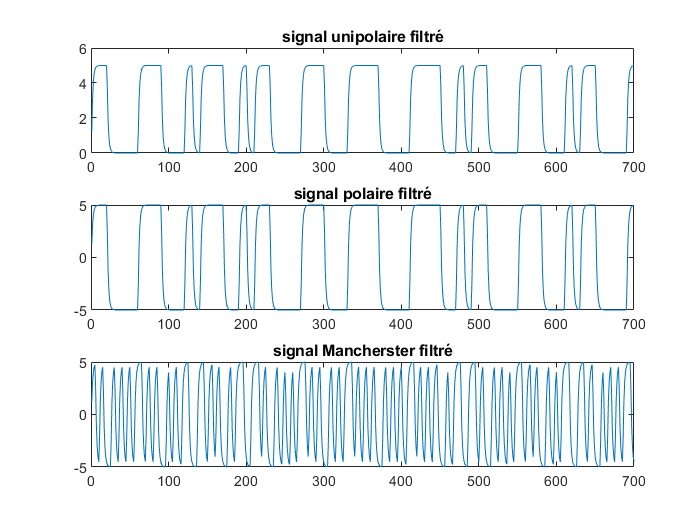

fc = 1/Tm;
[b, a] = butter(1, (fc/Fe)*2);
% unipolaire
filt_un = filter(b, a, sUnipolaire);
sb_un = awgn(filt_un, 1000, 'measured');           % sb-> signal bas (aprés la filtrage)
figure; subplot(3,1,1); plot(sb_un); title('signal unipolaire filtré');
% polaire
filt_pol = filter(b, a, sPolaire);
sb_pol = awgn(filt_pol, 1000, 'measured');
subplot(3,1,2); plot(sb_pol); title('signal polaire filtré');
% Mancherster
filt_man = filter(b, a, sMancherster);
sb_man = awgn(filt_man, 1000, 'measured');
subplot(3,1,3); plot(sb_man); title('signal Mancherster filtré')

% unitaire
seuil = (max(sb_un) - min(sb_un))/2;

Unrecognized function or variable 'sb_un'.

sb_se = sb(sb_un : spb : end);
sb_dec = sb_se > seuil;
% polaire
seuil = (max(sb_pol) - min(sb_pol))/2;
sb_se = sb(sb_pol : spb : end);
sb_dec = sb_se > seuil;
% Mancherster



tentativa própia

% unitaire 
max = 5;
min = 0;
moienne_un = (max - min)/2;

N = 700;

reconsttrution_un = zeros(N);

for i = 1:N
    if sb_un(i) <  moienne_un
        reconsttrution_un(i) = min;  
    else
        reconsttrution_un(i) = max; 
    end
end

Unrecognized function or variable 'sb_un'.



figure; subplot(2,1,1); plot(sb_un); title('signal unipolaire filtré');
subplot(2,1,2); plot(reconsttrution_un); title('signal unipolaire reconstruite');

